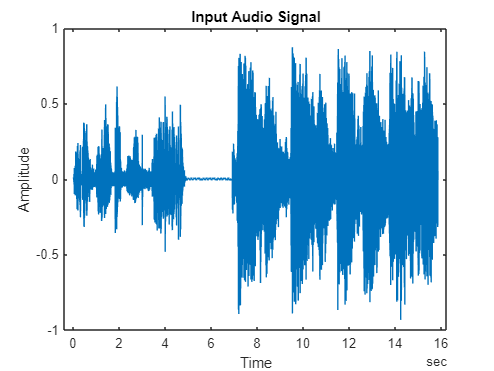

clc ;
clear all ;
close all ;

[data ,Fs] = audioread('test.wav');
t = seconds(0:1/Fs:(size(data,1)-1)/Fs);
plot(t,data)
title('Input Audio Signal');
xlabel('Time');
ylabel('Amplitude');

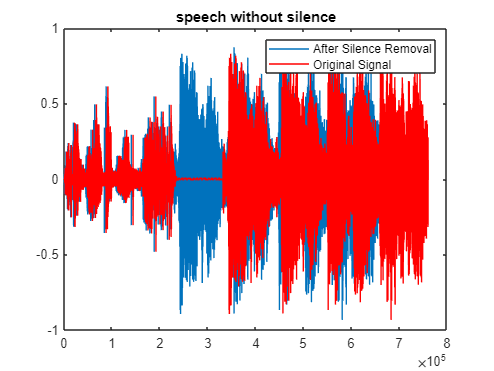

%sound(data , Fs) ;

f_d = 0.025;
f_size = round(f_d * Fs);
n = length(data);
n_f = floor(n/f_size);  %no. of frames
temp = 0;
for i = 1 : n_f
    
   frames(i,:) = data(temp + 1 : temp + f_size);
   temp = temp + f_size;
end

m_amp = abs(max(frames,[],2)); % find maximum of each frame
id = find(m_amp > 0.03); % finding ID of frames with max amp > 0.03
fr_ws = frames(id,:); % frames without silence

data_r = reshape(fr_ws',1,[]);
plot(data_r); title('speech without silence');
hold on;
plot(data,'r');
legend('After Silence Removal','Original Signal');

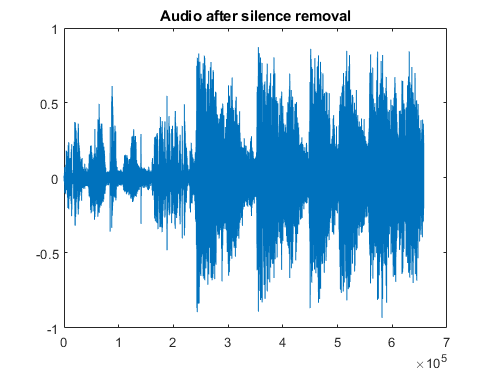


figure ;
plot(data_r);
title('Audio after silence removal')

%sound(data_r , Fs)

figure;
